% c1~=c2, =init_con
hold on
time = [1 3000];

%% oxygen
o2_data = []; %just for later plotting
save o2data.mat o2_data;

v3 = 10; %default o2 into system 
a3 = 0.1; %o2 out of system 

% cell death (% per cell cycle?)
delta1 = 0.1 

delta1 = 0.1000

delta2 = 0.1; %initially same

%% cells
%cell cycle rate
r = 0.33; %# of div per day
mut = 0.004; %mut rate

% "symmetric" division probability (N-->N, M-->M)
gamma1 = (1-mut)^2;
gamma2 = 1; %cancer can't "go back"  

% mutated division probability (for normal cells)
p2 = 2*(mut)*(1-mut); %N --> N,M (no net change in # of N)
p3 = (mut)^2; %N --> M,M (-1 net N)
 
%% normal-cancer interactions
cp = 50; %carrying capacity (entire cell population)
c1 = 0.005

c1 = 0.0050

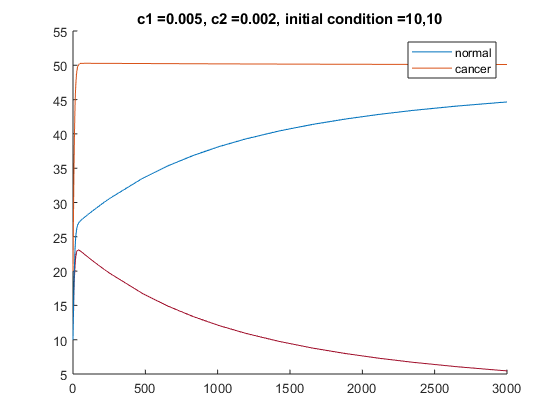

c2 = 0.002; 


%% 

%% Solve ODEs
init_con = [10 10];
options = odeset('NonNegative', [1 2]); 



ol = ode15s(@(t,x) LV_ODEs3(t,x,r,v3,a3,gamma1,gamma2,delta1,delta2,p2,p3,c1,c2,cp), time, init_con, options);

%% Plot

plot(sol.x,sol.y,sol.x, sum(sol.y),'-')
legend('normal','cancer');
title(['c1 =' num2str(c1) ', c2 =' num2str(c2) ', initial condition =' num2str(init_con(1)) ',' num2str(init_con(2))]);

hold on